%此程序用于计算大口径光子筛的衍射图样
t1=clock;
f1=0.4;
D1=0.2;
lamda1=656.45e-9;
eta1=1.2;
k=2*pi/lamda1; % 波数

load sample1_hole.mat
load sample1_para.mat

%用于处理内环
X=meshgrid(-2e-5:1e-7:2e-5);
Y=meshgrid(-2e-5:1e-7:2e-5).';
size1=size(X,1);
U1=zeros(size1,size1);
for i=1:3968 %由前二十环记点得
    an=0.5*double(hole1(3,i));
    xn=double(hole1(1,i));
    yn=double(hole1(2,i));
    U1=U1+U_n(X,Y,k,1,f1,0,an,xn,yn,0,0);
end

%用于处理外环
U2R=zeros(1,201);%取样间隔1e-6
%这用于获得一个径向的分布
for m=21:N1
    U2R=U2R+U_m(para(3,m),k,1,f1,para(4,m)/2,para(1,m),0:1e-7:2e-5);
end

U1R=U1(201,201:end);
U3R=U1R+U2R;
U3R=abs(U3R);
t2=clock;
etime(t2,t1)

ans = 764.6720

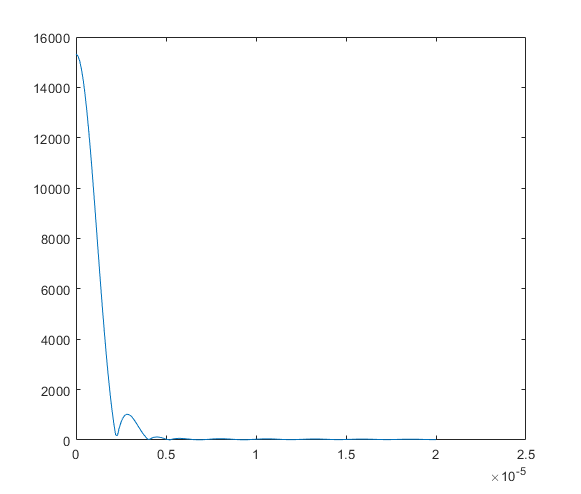

plot(0:1e-7:2e-5,U3R)

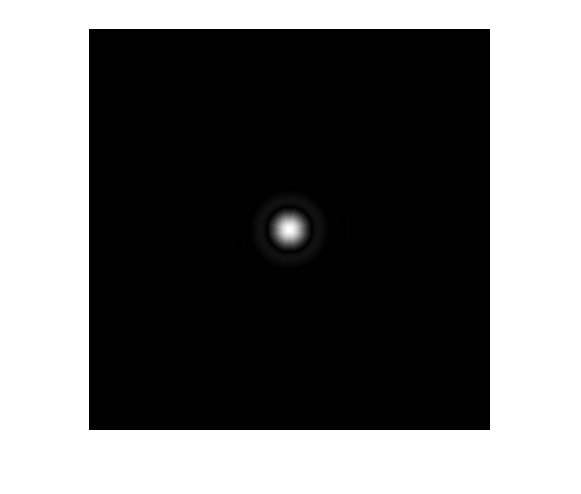

U2=zeros(size1,size1);
%反正这个计算需要的资源不多,再跑一遍吧,来获得一个稍大点的圆覆盖我的范围
U2R=zeros(1,301);
for m=21:N1
    U2R=U2R+U_m(para(3,m),k,1,f1,para(4,m)/2,para(1,m),0:1e-7:3e-5);
end

for i=1:size1
    for j=1:size1
        r=fix(((i-201)^2+(j-201)^2)^0.5)+1;
        U2(i,j)=U2R(1,r);
    end
end

U3=abs(U1+U2);
%U3=log10(U3);
U3_max=max(max(U3));
U3=U3./U3_max;
save sample1_end U3
imshow(U3)

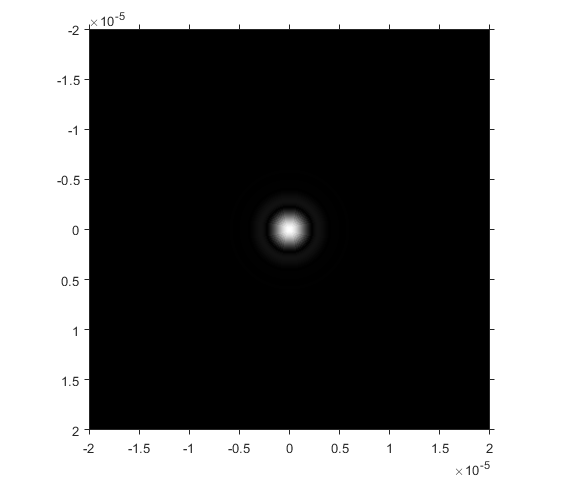

RI = imref2d(size(U3));
RI.XWorldLimits = [-2e-5 2e-5];
RI.YWorldLimits = [-2e-5 2e-5];
figure
imshow(U3,RI)

function U1=U_n(X,Y,k,An,q,Ln,an,xn,yn,gn,hn)
%我希望X,Y是矩阵
%An孔径中心的振幅,近似代表整个,L_n,孔径中心的相位等效光程,(2.24)
    H=(q^2+(X-xn).^2+(Y-yn).^2).^0.5;
    rou=((X-xn-gn.*H).^2+(Y-yn-hn.*H).^2).^0.5;
    U1=(k*An*q*an^2./(H.^2)).*exp(1j*k*(H+Ln)).*besselj(1,k*an*rou./H)./(k*an*rou./H);
end

function U2=U_m(Nm,k,Am,q,am,rm,R)
%以环带模型计算每环带的谱,记得考略环带模型的限制条件,以及后续可能需要评估一下精度误差
H0=(q^2+R.^2+rm^2).^0.5;
U2=Nm*k*Am*q*am^2./H0.^2.*besselj(1,k*am*rm./H0)./(k*am*rm./H0).*exp(1j*k*H0).*besselj(0,k*R*rm./H0);
end